# Модуляция с остаточной боковой полосой

# Vestigial Side Band

# (VSB)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Ниже представлен скрипт для получения спектра однополосного сигнала при модуляции аудиосообщением. С помощью переменной ModulationMethod можно выбрать, какой сигнал будет сформирован: USB или LSB. Считая, что полоса аудиосигнала равна 22 kHz, перед низкочастотной фильтрацией сообщение должно быть сдвинуто на -15 kHz для USB, и на 15 kHz для LSB. 

Чтобы сдвинуть сигнал на частоту несущей, после низкочастотной фильтрации его необходимо сдвинуть обратно на 15 kHz. Это можно сделать сразу во время переноса на несущую, умножая сигнал на комплексную экспоненту, частота которой равна сумме частоты несущей и частоты сдвига.

### 2. Модулятор VSB

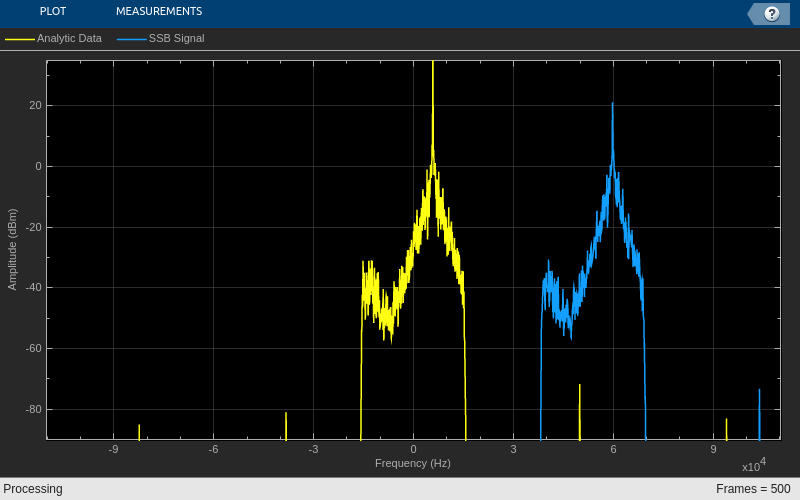

clc; clear; close all;
addpath('matlab/VSB');

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 500;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации
Ac = 2;                 % амплитуда несущей

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор тона с частотой 11 kHz
BasebandMixer = dsp.SineWave(...
    'SampleRate', AudioFs,...
    'SamplesPerFrame', AudioFrameSize,...
    'Frequency', 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% расчет коэффициентов и создание низкочастотного фильтра
H = Transmitter_Baseband_FIR_Coeff(); 
BasebandFIR = dsp.FIRFilter(H.Numerator);

% генератор несущей с частотой 60 kHz
Carrier_USB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

Carrier_LSB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 - 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Data', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

VSBAmSignalArray = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % добавление постоянной составляющей
    AudioData = AudioData + Ac;

    % формирование тона для переноса сперктра
    MixerWave = BasebandMixer(); 

    % фильтрация для удаления второй полосы
    if (ModulationMethod == "LSB")
        VSBData = BasebandFIR(AudioData.*MixerWave);
    else
        VSBData = BasebandFIR(AudioData.*conj(MixerWave));
    end

    % увеличение частоты дискретизации аудиосообщения
    UpsampledData = Upsampler(VSBData);
     
    % формирование несущей
    if (ModulationMethod == "LSB")
        CarrierWave = Carrier_LSB();    
    else
        CarrierWave = Carrier_USB();
    end

    % перенос на частоту несущей
    VSBAmSignal = UpsampledData.*CarrierWave;
    VSBAmSignalArray = [VSBAmSignalArray VSBAmSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([UpsampledData, VSBAmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Желтым цветом на графике представлен спектр сообщения после низкочастотной фильтрации, а синим - спектр модулированного сигнала. Можно увидеть, что получены те же результаты, что и при использовании полосового фильтра и преобразования Гильберта.

ModulationMethod задает вид модуляции (USB или LSB).

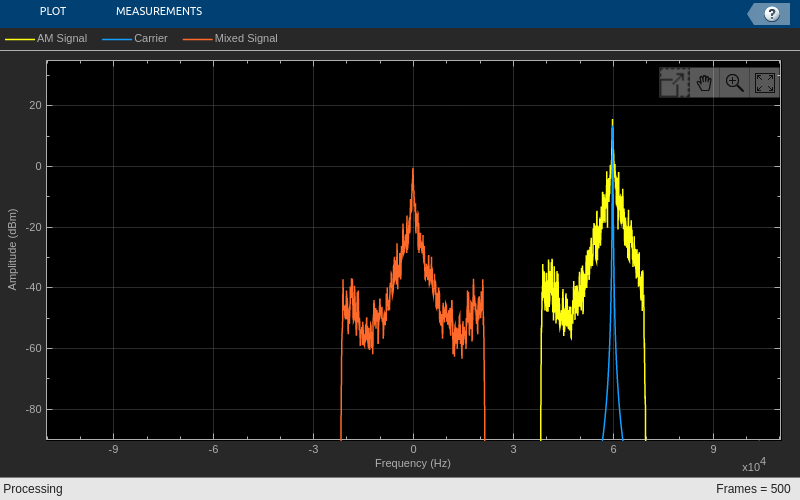

AudioAmp = 1; % коэффициент усиления аудиосигнала

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% генератор несущей для двух пользователей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + FreqOffset,...
    'PhaseOffset', PhaseOffset, ...
    'ComplexOutput', true, ...
    'Amplitude', 1 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber

    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);

    % получение несущей
    CarrierWave = Carrier();

    % смешивание АМ-сигнала и несущей
    MixedSignal = VSBAmSignal .* conj(CarrierWave);
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([VSBAmSignal CarrierWave MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.03)
end

asdsad

% проигрывание полученного сообщения
sound(Message, AudioFs);

Ниже представлен скрипт, выполняющий описанные выше преобразования:

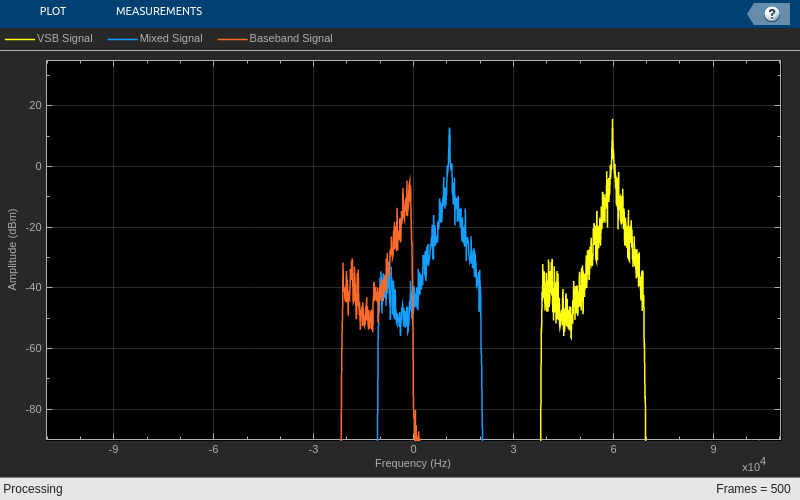

addpath('matlab/SSB_SC');

AudioAmp = 1; % коэффициент усиления аудиосигнала

% генератор несущей с частотой 60 kHz
Carrier_USB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

Carrier_LSB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 - 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% расчет коэффициентов и создание низкочастотного фильтра
H = Receiver_Baseband_FIR_Coeff(); 
BasebandFIR = dsp.FIRFilter(H.Numerator);

% генераторы для переноса сигнала на нулевую частоту
BasebandMixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1 ...
    );

% дециматор
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'VSB Signal', 'Mixed Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);
    
    % получение несущей
    if (ModulationMethod == "LSB")
        CarrierWave = Carrier_LSB();
    else
        CarrierWave = Carrier_USB();
    end
    
    % смещение сигналов по частоте
    MixedData = VSBAmSignal .* conj(CarrierWave);
    
    % низкочастотная фильтрация
    FilteredData = BasebandFIR(MixedData);
    
    % получения комплексной экспоненты для компенсации сдвига по частоте
    BasebandWave = BasebandMixer();

    % компенсация сдвига по частоте
    if (ModulationMethod == "LSB")
        BasebandData = FilteredData .* conj(BasebandWave);
    else
        BasebandData = FilteredData .* BasebandWave;
    end

    % децимация
    AudioData = real(DownSampler(BasebandData));
    
    Message = [Message; AudioData];

    % вычисление спектров
    SpectrumData = SpecEstimator([VSBAmSignal MixedData BasebandData]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме можно увидеть разделенные сообщения от первого (желтый) и второго (синий) пользователя . Из-за того, что низкочастотный фильтр имеет конечное ослабление в полосе подавления, низкочастотные спектранльные компоненты от первого пользователя попадают ко второму. Однако, они ослаблены до уровня -40 dB. В зависимости от решаемой задачи и технических требований этого может быть достаточно, а может быть и нет. Также можно увидеть, что из аудиосообщения удалены низкочастотные составляющие спектра.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что удаления низкочастотных спектральных компенент из аудиосообщения на вносит существенных искажений.

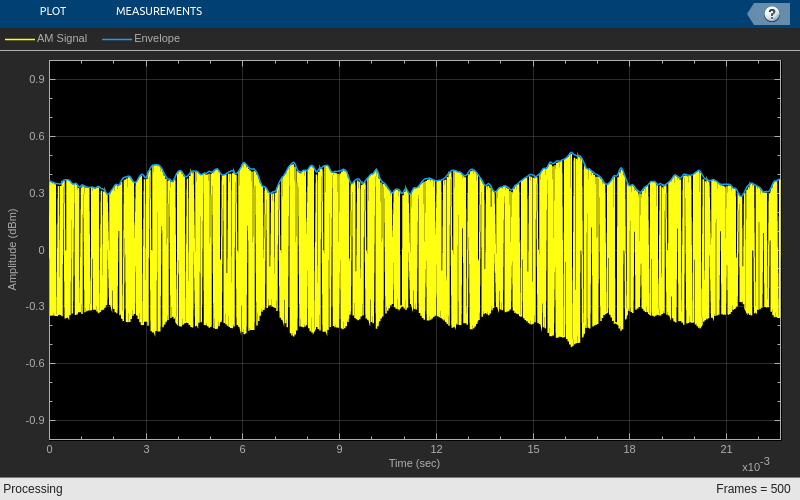

AudioAmp = 0.2; % коэффициент усиления аудиосигнала

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);

    % вычисление амплитуды сигнала
    AbsVSBAmSignal = abs(VSBAmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(AbsVSBAmSignal)];

    % вывод результатов на график
    Plotter([AudioAmp*real(VSBAmSignal) AudioAmp*AbsVSBAmSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены временные диаграммы сигналов на входе (желтый цвет,принятом сообщении действительная составляющая) и выходе (синий цвет) демодулятора. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR